# Lorenz

Formulate the model before implementing problem in code.


$$\dot{vv} = \left\{ \matrix{  \dot{x} \cr \dot{y} \cr \dot{z}} \right\} = 
\left\{ \matrix{ 
\sigma (y-x) \cr 
x(\rho - z) -y \cr 
xy - \beta z} \right\}$$


Create a local function **lorenz_rate **that implements the Lorenz equations.  While the [book's example code ](https://github.com/bsb808/PhysicalModelingInMatlab/blob/ae2440-dev/code/chap_matrices/lorenz.m)explicity unpacked and repacked the state vector, we'll operate directly on the state vector.

function dot_vv = lorenz_rate(t, vv)
    % Set the parameters
    sigma = 10;
    beta = 8/3;
    rho = 28;
    dot_vv = [sigma * (vv(2)-vv(1)) ;
        vv(1)*(rho - vv(3)) - vv(2) ;
        vv(1)*vv(2) - beta*vv(3)];
end


Test the function by calling it from the main function with values like t = 0, x = 1, y = 2, and z = 3. 

rate = lorenz_rate(0, [1 2 3])

rate =     10
    23
    -6


Use `ode45`  to estimate the solution for the time span [0, 30] with the initial condition x(0) = 1, y(0) = 2, and z(0) = 3.

tspan = [0 30];
vv_init = [1 2 3];
options = odeset('Stats','on');
[tt, V] = ode45(@lorenz_rate, tspan, vv_init, options);

410 successful steps
65 failed attempts
2851 function evaluations


Plot the results as a time series, that is, each of the variables from the state vector as a function of time.

Unpack the matrix output from ode45 into three vectors

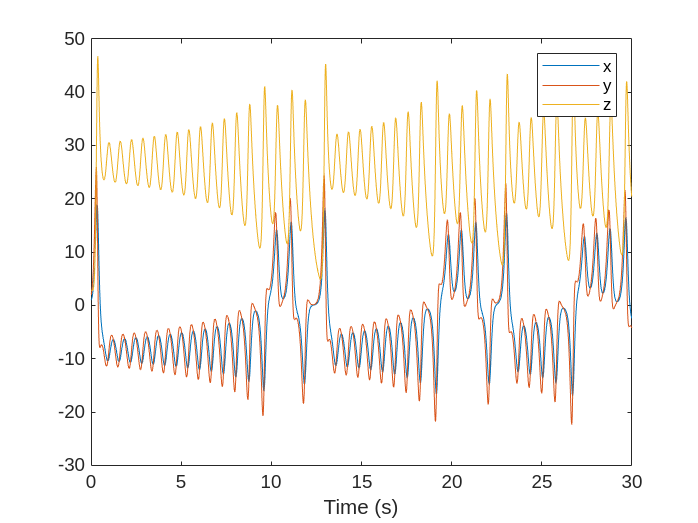

figure;
clf;
xx = V(:,1);
yy = V(:,2);
zz = V(:,3);
plot(tt, xx, tt, yy, tt, zz)
xlabel("Time (s)")
legend('x', 'y', 'z')

Plot all three time series at once by plotting the time vector vs. the solution matrix.

figure;
clf;
plot(tt,V)
xlabel("Time (s)")
legend('x', 'y', 'z')

Use `plot3`  to plot the trajectory of x, y , and z .

figure;
clf;
plot3(xx, yy, zz)
xlabel("x")
ylabel("y")
zlabel("z")


If you rotate the figure you should see a view like this.

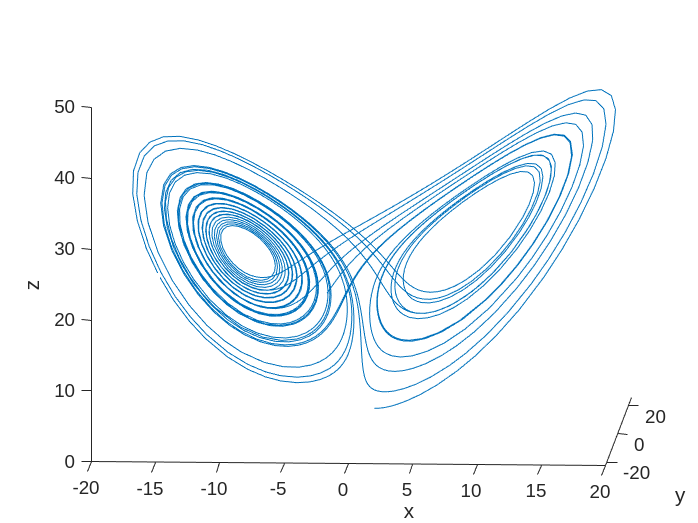

xlim([-20.0 20.0])
ylim([-22.3 26.1])
zlim([0.0 50.0])
view([2.9 10.9])